# **LAB 2: REALTIME**

% load variables in workspace (parameters according to motor 8)
load params_inertial_case.mat
load params_estimated_LAB0.mat
load PID_params_LAB0.mat
load filters.mat
sens.enc.pulse2deg = 360/4096; %CAMBIA IN 360/4096

## **3.1 Part 1: position PID-controller**

   1) backward Euler

% open simulink model
open_system('REALTIME_PART1_backwardEuler.slx');

step_size = 50;
Tl=1/(2*ctrl.w_gc);
K_w=0;

%SIMULATION sampling time T1
T=0.001;

%sim('REALTIME_PART1_backwardEuler.slx');
data2.backe.samplingT1.t            = MotorData.time;
data2.backe.samplingT1.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.backe.samplingT1.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.samplingT1.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.backe.samplingT1.acc_meas     = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.backe.samplingT1.u_control    = MotorData.signals(4).values(:,1);     % control input  [V]
data2.backe.samplingT1.u_presat     = MotorData.signals(4).values(:,2);
data2.backe.samplingT1.err          = MotorData.signals(5).values;          % tracking error [deg]

%SIMULATION sampling time T2
T=0.01;

%sim('REALTIME_PART1_backwardEuler.slx');
data2.backe.samplingT2.t            = MotorData.time;
data2.backe.samplingT2.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.backe.samplingT2.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.samplingT2.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.backe.samplingT2.acc_meas     = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.backe.samplingT2.u_control    = MotorData.signals(4).values(:,1);     % control input  [V]
data2.backe.samplingT2.u_presat     = MotorData.signals(4).values(:,2);
data2.backe.samplingT2.err          = MotorData.signals(5).values;          % tracking error [deg]

%SIMULATION sampling time T3
T=0.05;

%sim('REALTIME_PART1_backwardEuler.slx');
data2.backe.samplingT3.t            = MotorData.time;
data2.backe.samplingT3.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.backe.samplingT3.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.samplingT3.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.backe.samplingT3.acc_meas     = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.backe.samplingT3.u_control    = MotorData.signals(4).values(:,1);     % control input  [V]
data2.backe.samplingT3.u_presat     = MotorData.signals(4).values(:,2);
data2.backe.samplingT3.err          = MotorData.signals(5).values;          % tracking error [deg]

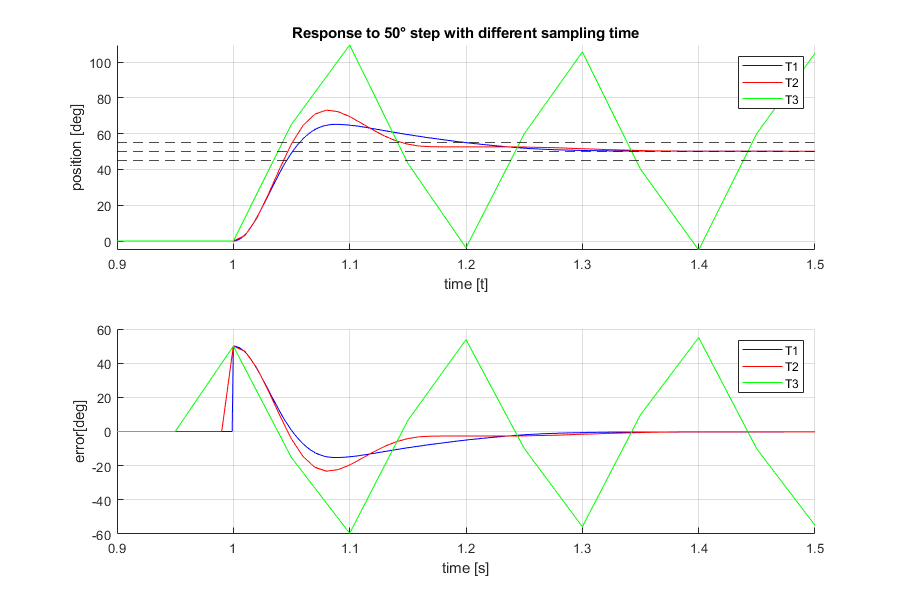

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2,1,1);
hold on;
plot(data2.backe.samplingT1.t,data2.backe.samplingT1.thl_meas,'b');
plot(data2.backe.samplingT2.t,data2.backe.samplingT2.thl_meas,'r');
plot(data2.backe.samplingT3.t,data2.backe.samplingT3.thl_meas,'g');
yline(50,'k--')
yline(45,'k--')
yline(55,'k--')
hold off;
legend('T1','T2','T3');
title('Response to 50° step with different sampling time')
xlabel('time [t]');
ylabel('position [deg]');
grid on;
xlim([0.9,1.5]);

subplot(2,1,2);
hold on;
plot(data2.backe.samplingT1.t,data2.backe.samplingT1.err,'b');
plot(data2.backe.samplingT2.t,data2.backe.samplingT2.err,'r');
plot(data2.backe.samplingT3.t,data2.backe.samplingT3.err,'g');
hold off;
xlabel('time [s]');
ylabel('error[deg]');
legend('T1','T2','T3');
grid on
xlim([0.9,1.5]);

stepinfo(data2.backe.samplingT1.thl_meas,data2.backe.samplingT1.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0337
    SettlingTime: 1.2396
     SettlingMin: 45.1758
     SettlingMax: 65.2148
       Overshoot: 30.6338
      Undershoot: 0
            Peak: 65.2148
        PeakTime: 1.0860


stepinfo(data2.backe.samplingT2.thl_meas,data2.backe.samplingT2.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0311
    SettlingTime: 1.2528
     SettlingMin: 50.0098
     SettlingMax: 73.2129
       Overshoot: 46.3972
      Undershoot: 0
            Peak: 73.2129
        PeakTime: 1.0800


2) anti windup

K_w=0;
T=0.01;
step_size=360;

% SIMULATION WITHOUT AWU
%sim('REALTIME_PART1_backwardEuler.slx');
data2.backe.noawu.t            = MotorData.time;
data2.backe.noawu.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.backe.noawu.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.noawu.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.backe.noawu.acc_meas     = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.backe.noawu.u_control    = MotorData.signals(4).values(:,1);     % control input  [V]
data2.backe.noawu.u_presat     = MotorData.signals(4).values(:,2); 
data2.backe.noawu.err          = MotorData.signals(5).values;          % tracking error [deg]

K_w = 15;

% SIMULATION WITH AWU  
%sim('REALTIME_PART1_backwardEuler.slx');
data2.backe.awu.t            = MotorData.time;
data2.backe.awu.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.backe.awu.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.awu.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.backe.awu.acc_meas     = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.backe.awu.u_control    = MotorData.signals(4).values(:,1);     % control input  [V]
data2.backe.awu.u_presat     = MotorData.signals(4).values(:,2); 
data2.backe.awu.err          = MotorData.signals(5).values;          % tracking error [deg]

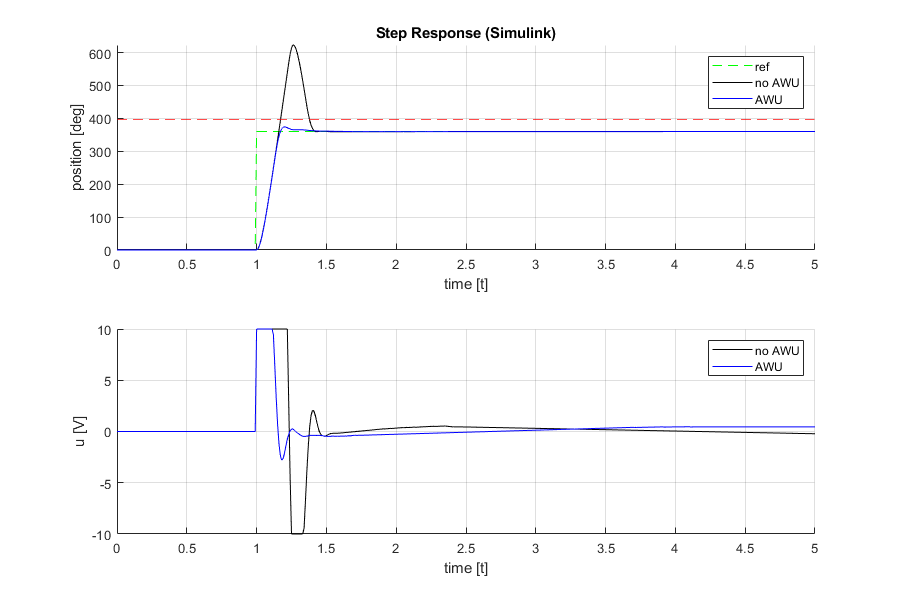

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2,1,1);
hold on;
plot(data2.backe.noawu.t,data2.backe.noawu.thl_ref,'g--');
plot(data2.backe.noawu.t,data2.backe.noawu.thl_meas,'k');
plot(data2.backe.awu.t,data2.backe.awu.thl_meas,'b');
title('Step Response (Simulink)')
xlabel('time [t]');
ylabel('position [deg]');
grid on;
yline(step_size*1.1,'r--');
hold off;
legend('ref','no AWU','AWU');

subplot(2,1,2);
hold on;
plot(data2.backe.noawu.t,data2.backe.noawu.u_control,'k');
plot(data2.backe.awu.t,data2.backe.awu.u_control,'b');
xlabel('time [t]');
ylabel('u [V]');
legend('no AWU','AWU');
grid on;
hold off;

data2.backe.noawu.stepinfo = stepinfo(data2.backe.noawu.thl_meas,data2.backe.noawu.t,'SettlingTimeThreshold',0.05)

data2 = struct with fields:
    backe: [1×1 struct]


data2.backe.awu.stepinfo   = stepinfo(data2.backe.awu.thl_meas,data2.backe.awu.t,'SettlingTimeThreshold',0.05)

data2 = struct with fields:
    backe: [1×1 struct]


3) Discrete time feedforward compensation scheme

% Feedforward params
inertia_comp = gbox.N*Req*Jeq_hat /(drv.dcgain*mot.Kt);
friction_comp = Req/(drv.dcgain*mot.Kt*gbox.N);
BEMF_comp = gbox.N*mot.Ke/drv.dcgain;  
Beq = Beq_hat;                           % mot.B + mld.B/gbox.N^2;    
Jeq = Jeq_hat;
T=0.01; %sampling time

% open simulink model
open_system('REALTIME_PART1_discretefeedforward.slx');

K_w = 15;

% SIMULATION WITHOUT FEEDFORWARD
%sim('REALTIME_PART1_discretefeedforward.slx');
data2.backe.noff.t        = MotorData.time;
data2.backe.noff.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data2.backe.noff.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.noff.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data2.backe.noff.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data2.backe.noff.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data2.backe.noff.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data2.backe.noff.u        = MotorData.signals(4).values;          % control input  [V]
data2.backe.noff.err      = MotorData.signals(5).values;          % tracking error [deg]

% SIMULATION WITH FEEDFORWARD (CAMBIA IL SIMULINK)
%sim('REALTIME_PART1_discretefeedforward.slx');
data2.backe.ff.t        = MotorData.time;
data2.backe.ff.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data2.backe.ff.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.ff.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data2.backe.ff.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data2.backe.ff.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data2.backe.ff.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data2.backe.ff.u        = MotorData.signals(4).values;          % control input  [V]
data2.backe.ff.err      = MotorData.signals(5).values;          % tracking error [deg]

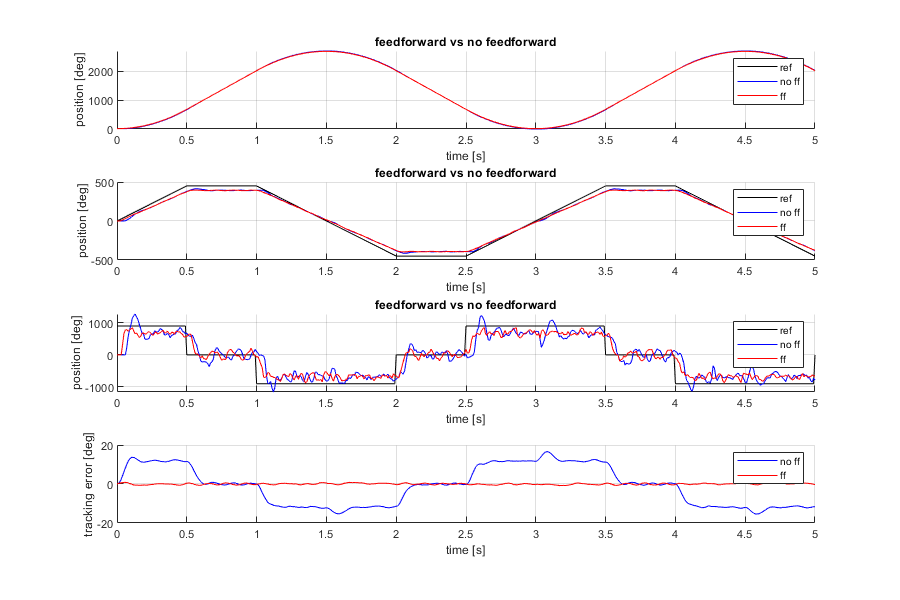

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(4,1,1);
hold on;
plot(data2.backe.noff.t,data2.backe.noff.thl_ref,'k');
plot(data2.backe.noff.t,data2.backe.noff.thl_meas,'b');
plot(data2.backe.ff.t,data2.backe.ff.thl_meas,'r');
hold off;
legend('ref','no ff','ff');
xlabel('time [s]');
ylabel('position [deg]');
title('feedforward vs no feedforward');
grid on;

subplot(4,1,2);
hold on;
plot(data2.backe.noff.t,data2.backe.noff.wl_ref,'k');
plot(data2.backe.noff.t,data2.backe.noff.wl_meas,'b');
plot(data2.backe.ff.t,data2.backe.ff.wl_meas,'r');
hold off;
legend('ref','no ff','ff');
xlabel('time [s]');
ylabel('position [deg]');
title('feedforward vs no feedforward');
grid on;

subplot(4,1,3);
hold on;
plot(data2.backe.noff.t,data2.backe.noff.acc_ref,'k');
plot(data2.backe.noff.t,data2.backe.noff.acc_meas,'b');
plot(data2.backe.ff.t,data2.backe.ff.acc_meas,'r');
hold off;
legend('ref','no ff','ff');
xlabel('time [s]');
ylabel('position [deg]');
title('feedforward vs no feedforward');
grid on;

subplot(4,1,4);
hold on;
plot(data2.backe.noff.t,data2.backe.noff.err,'b');
plot(data2.backe.ff.t,data2.backe.ff.err,'r');
legend('no ff','ff');
xlabel('time [s]');
ylabel('tracking error [deg]');
hold off;
grid on

K_w = 0;

% SIMULATION WITHOUT FEEDFORWARD
%sim('REALTIME_PART1_discretefeedforward.slx');
data2.backe.noff.noaw.t        = MotorData.time;
data2.backe.noff.noaw.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data2.backe.noff.noaw.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.noff.noaw.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data2.backe.noff.noaw.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data2.backe.noff.noaw.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data2.backe.noff.noaw.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data2.backe.noff.noaw.u        = MotorData.signals(4).values;          % control input  [V]
data2.backe.noff.noaw.err      = MotorData.signals(5).values;          % tracking error [deg]

% SIMULATION WITH FEEDFORWARD (CAMBIA IL SIMULINK)
%sim('REALTIME_PART1_discretefeedforward.slx');
data2.backe.ff.noaw.t        = MotorData.time;
data2.backe.ff.noaw.thl_ref  = MotorData.signals(1).values(:,1);     % reference angle input [deg]
data2.backe.ff.noaw.thl_meas = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.backe.ff.noaw.wl_ref   = MotorData.signals(2).values(:,1);     % reference speed input [deg]
data2.backe.ff.noaw.wl_meas  = MotorData.signals(2).values(:,2);     % speed measured [deg]
data2.backe.ff.noaw.acc_ref  = MotorData.signals(3).values(:,1);     % reference acc input [deg]
data2.backe.ff.noaw.acc_meas = MotorData.signals(3).values(:,2);     % acc measured [deg]
data2.backe.ff.noaw.u        = MotorData.signals(4).values;          % control input  [V]
data2.backe.ff.noaw.err      = MotorData.signals(5).values;          % tracking error [deg]

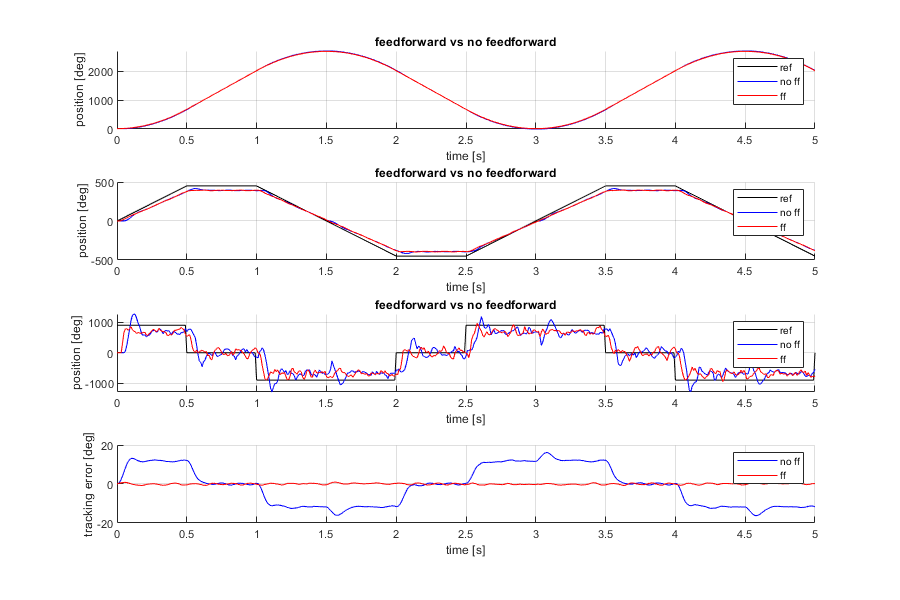

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(4,1,1);
hold on;
plot(data2.backe.noff.noaw.t,data2.backe.noff.noaw.thl_ref,'k');
plot(data2.backe.noff.noaw.t,data2.backe.noff.noaw.thl_meas,'b');
plot(data2.backe.ff.noaw.t,data2.backe.ff.noaw.thl_meas,'r');
hold off;
legend('ref','no ff','ff');
xlabel('time [s]');
ylabel('position [deg]');
title('feedforward vs no feedforward');
grid on;

subplot(4,1,2);
hold on;
plot(data2.backe.noff.noaw.t,data2.backe.noff.noaw.wl_ref,'k');
plot(data2.backe.noff.noaw.t,data2.backe.noff.noaw.wl_meas,'b');
plot(data2.backe.ff.noaw.t,data2.backe.ff.noaw.wl_meas,'r');
hold off;
legend('ref','no ff','ff');
xlabel('time [s]');
ylabel('position [deg]');
title('feedforward vs no feedforward');
grid on;

subplot(4,1,3);
hold on;
plot(data2.backe.noff.noaw.t,data2.backe.noff.noaw.acc_ref,'k');
plot(data2.backe.noff.noaw.t,data2.backe.noff.noaw.acc_meas,'b');
plot(data2.backe.ff.noaw.t,data2.backe.ff.noaw.acc_meas,'r');
hold off;
legend('ref','no ff','ff');
xlabel('time [s]');
ylabel('position [deg]');
title('feedforward vs no feedforward');
grid on;

subplot(4,1,4);
hold on;
plot(data2.backe.noff.noaw.t,data2.backe.noff.noaw.err,'b');
plot(data2.backe.ff.noaw.t,data2.backe.ff.noaw.err,'r');
legend('no ff','ff');
xlabel('time [s]');
ylabel('tracking error [deg]');
hold off;
grid on

Different methods

% open simulink model
open_system('REALTIME_PART1_differentmethods.slx');

step_size=50;
z = tf('z',T);
s = tf('s');
Cs = ctrl.Kp + ctrl.Ki / s + ctrl.Kd *s / ( Tl*s +1); % continuos tf

Forward Euler

T = 0.001;
Cz_ffeuler = minreal(ctrl.Kp + ctrl.Ki * T /(z-1) + ctrl.Kd *(z-1) / ( (Tl)*z-Tl+T)); % forward euler
[num_Cz den_Cz] = tfdata(Cz_ffeuler,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.forwe.samplingT1.t         = MotorData.time;
data2.forwe.samplingT1.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.forwe.samplingT1.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.forwe.samplingT1.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.forwe.samplingT1.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.forwe.samplingT1.u_control = MotorData.signals(4).values;          % control input  [V]
data2.forwe.samplingT1.err       = MotorData.signals(5).values;          % tracking error [deg]

T = 0.01;
Cz_ffeuler = minreal(ctrl.Kp + ctrl.Ki * T /(z-1) + ctrl.Kd *(z-1) / ( (Tl)*z-Tl+T)); % forward euler
[num_Cz den_Cz] = tfdata(Cz_ffeuler,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.forwe.samplingT2.t         = MotorData.time;
data2.forwe.samplingT2.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.forwe.samplingT2.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.forwe.samplingT2.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.forwe.samplingT2.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.forwe.samplingT2.u_control = MotorData.signals(4).values;          % control input  [V]
data2.forwe.samplingT2.err       = MotorData.signals(5).values;          % tracking error [deg]

T = 0.05;
Cz_ffeuler = minreal(ctrl.Kp + ctrl.Ki * T /(z-1) + ctrl.Kd *(z-1) / ( (Tl)*z-Tl+T)); % forward euler
[num_Cz den_Cz] = tfdata(Cz_ffeuler,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.forwe.samplingT3.t         = MotorData.time;
data2.forwe.samplingT3.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.forwe.samplingT3.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.forwe.samplingT3.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.forwe.samplingT3.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.forwe.samplingT3.u_control = MotorData.signals(4).values;          % control input  [V]
data2.forwe.samplingT3.err       = MotorData.signals(5).values;          % tracking error [deg]

Tustin

T = 0.001;
Cz_tustin =minreal( c2d(Cs,T,'tustin'));
[num_Cz den_Cz] = tfdata(Cz_tustin,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.tustin.samplingT1.t         = MotorData.time;
data2.tustin.samplingT1.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.tustin.samplingT1.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.tustin.samplingT1.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.tustin.samplingT1.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.tustin.samplingT1.u_control = MotorData.signals(4).values;          % control input  [V]
data2.tustin.samplingT1.err       = MotorData.signals(5).values;          % tracking error [deg]

T = 0.01;
Cz_tustin =minreal( c2d(Cs,T,'tustin'));
[num_Cz den_Cz] = tfdata(Cz_tustin,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.tustin.samplingT2.t         = MotorData.time;
data2.tustin.samplingT2.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.tustin.samplingT2.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.tustin.samplingT2.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.tustin.samplingT2.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.tustin.samplingT2.u_control = MotorData.signals(4).values;          % control input  [V]
data2.tustin.samplingT2.err       = MotorData.signals(5).values;          % tracking error [deg]

T = 0.05;
Cz_tustin =minreal( c2d(Cs,T,'tustin'));
[num_Cz den_Cz] = tfdata(Cz_tustin,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.tustin.samplingT3.t         = MotorData.time;
data2.tustin.samplingT3.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.tustin.samplingT3.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.tustin.samplingT3.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.tustin.samplingT3.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.tustin.samplingT3.u_control = MotorData.signals(4).values;          % control input  [V]
data2.tustin.samplingT3.err       = MotorData.signals(5).values;          % tracking error [deg]

Exact (ZOH)

T = 0.001;
Cz_exact =minreal( c2d(Cs,T,'zoh'));
[num_Cz den_Cz] = tfdata(Cz_exact,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.exact.samplingT1.t         = MotorData.time;
data2.exact.samplingT1.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.exact.samplingT1.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.exact.samplingT1.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.exact.samplingT1.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.exact.samplingT1.u_control = MotorData.signals(4).values;          % control input  [V]
data2.exact.samplingT1.err       = MotorData.signals(5).values;          % tracking error [deg]

T = 0.01;
Cz_exact =minreal( c2d(Cs,T,'zoh'));
[num_Cz den_Cz] = tfdata(Cz_exact,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.exact.samplingT2.t         = MotorData.time;
data2.exact.samplingT2.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.exact.samplingT2.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.exact.samplingT2.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.exact.samplingT2.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.exact.samplingT2.u_control = MotorData.signals(4).values;          % control input  [V]
data2.exact.samplingT2.err       = MotorData.signals(5).values;          % tracking error [deg]

T = 0.05;
Cz_exact =minreal( c2d(Cs,T,'zoh'));
[num_Cz den_Cz] = tfdata(Cz_exact,'v');

%sim('REALTIME_PART1_differentmethods'); 
data2.exact.samplingT3.t         = MotorData.time;
data2.exact.samplingT3.thl_ref   = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.exact.samplingT3.thl_meas  = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.exact.samplingT3.wl_meas   = MotorData.signals(2).values;          % speed measured [rpm]
data2.exact.samplingT3.acc_meas  = MotorData.signals(3).values;          % acc measured [rpm/s]
data2.exact.samplingT3.u_control = MotorData.signals(4).values;          % control input  [V]
data2.exact.samplingT3.err       = MotorData.signals(5).values;          % tracking error [deg]

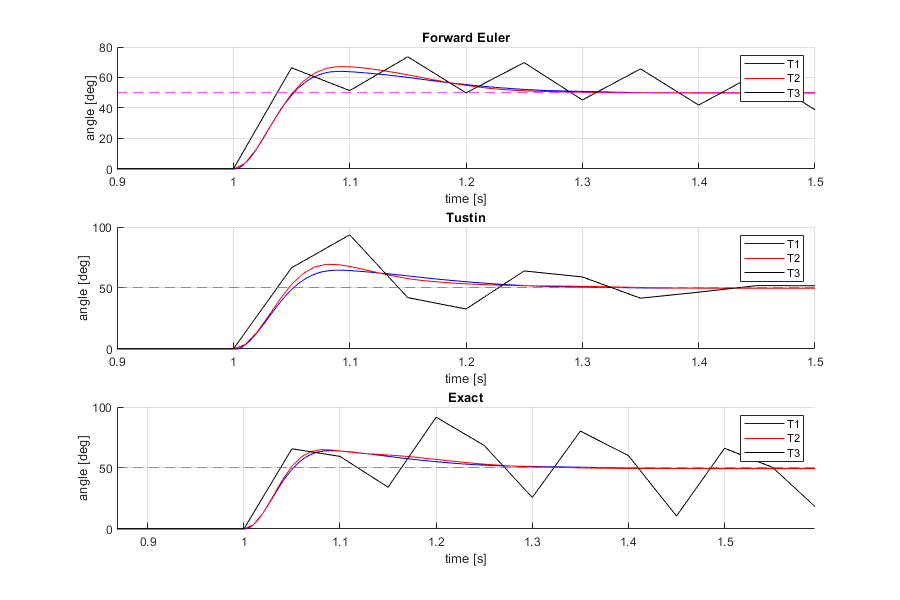

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(3,1,1);
hold on;
plot(data2.forwe.samplingT1.t,data2.forwe.samplingT1.thl_meas,'b');
plot(data2.forwe.samplingT2.t,data2.forwe.samplingT2.thl_meas,'r');
plot(data2.forwe.samplingT3.t,data2.forwe.samplingT3.thl_meas,'k');
yline(50,'m--')
xlim([0.9,1.5]);
hold off;
legend('T1','T2','T3');
title('Forward Euler');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

subplot(3,1,2);
hold on;
plot(data2.tustin.samplingT1.t,data2.tustin.samplingT1.thl_meas,'b');
plot(data2.tustin.samplingT2.t,data2.tustin.samplingT2.thl_meas,'r');
plot(data2.tustin.samplingT3.t,data2.tustin.samplingT3.thl_meas,'k');
yline(50,'m--')
xlim([0.9,1.5]);
hold off;
legend('T1','T2','T3');
title('Tustin');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

subplot(3,1,3);
hold on;
plot(data2.exact.samplingT1.t,data2.exact.samplingT1.thl_meas,'b');
plot(data2.exact.samplingT2.t,data2.exact.samplingT2.thl_meas,'r');
plot(data2.exact.samplingT3.t,data2.exact.samplingT3.thl_meas,'k');
yline(50,'m--')
xlim([0.9,1.5]);
hold off;
legend('T1','T2','T3');
title('Exact');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

## **3.1 Part 2: position state-space controller**

1) Nominal tracking with Forward Euler

% open simulink model
open_system('REALTIME_PART2_nominal.slx');


model.km = (drv.dcgain*mot.Kt)/(Req*Beq + mot.Kt*mot.Ke);
model.Tm = (Req*Jeq)/(Req*Beq + mot.Kt*mot.Ke);

%   non-encapsulated SS data
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;
%   SS data encapulated in a SS object
sys = ss(A, B, C, D);

T_ = eye(2);

%compute N_x, N_u
S = [A,B;C,0];
b=[0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);

%specs
spec.ts5    = 0.15;         % Settling-time
spec.Mp     = 0.1;          % Overshoot
spec.damp   = log(1/spec.Mp) / (sqrt(pi^2+(log(1/spec.Mp))^2));
spec.wn     = 3 / (spec.damp*spec.ts5);

%poles to place
Ts = tf([spec.wn^2],[1, 2*spec.damp*spec.wn,spec.wn^2]);
p=pole(Ts);
lambda0 = -ctrl.w_gc*5;

%Compute feedback matrix
K=place(A,B,p);

%Compute observer matrix
L= place(A(2,2).',A(1,2).',lambda0);
A0 = A(2,2) - L* A(1,2);
B0 =[ B(2) - L * B(1), (A(2,2) -L * A(1,2)) * L + A(2,1) - L * A(1,1)];
C0 = [0,1].';
D0 = [0,1 ; 0, L];

%DISCRETE TIME DESIGN FORWARD EULER
PHI = 1 + A0 * T;
GAMMA = B0 * T;
H0 = C0;
J0 = D0;
red_observer = ss(PHI, GAMMA, H0, J0); %reduced observer discrete

step_size = 50;

T = 0.001;
PHI = 1 + A0 * T;
GAMMA = B0 * T;
H0 = C0;
J0 = D0;

%sim('REALTIME_PART2_nominal.slx'); 
data2.nominal.forwe.samplingT1.t            = MotorData.time;
data2.nominal.forwe.samplingT1.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.nominal.forwe.samplingT1.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.nominal.forwe.samplingT1.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.nominal.forwe.samplingT1.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.nominal.forwe.samplingT1.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.01;
PHI = 1 + A0 * T;
GAMMA = B0 * T;
H0 = C0;
J0 = D0;

%sim('REALTIME_PART2_nominal.slx'); 
data2.nominal.forwe.samplingT2.t            = MotorData.time;
data2.nominal.forwe.samplingT2.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.nominal.forwe.samplingT2.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.nominal.forwe.samplingT2.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.nominal.forwe.samplingT2.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.nominal.forwe.samplingT2.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.05;
PHI = 1 + A0 * T;
GAMMA = B0 * T;
H0 = C0;
J0 = D0;

%sim('REALTIME_PART2_nominal.slx'); 
data2.nominal.forwe.samplingT3.t            = MotorData.time;
data2.nominal.forwe.samplingT3.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.nominal.forwe.samplingT3.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.nominal.forwe.samplingT3.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.nominal.forwe.samplingT3.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.nominal.forwe.samplingT3.u_control    = squeeze(MotorData.signals(4).values);          % control input  [V]

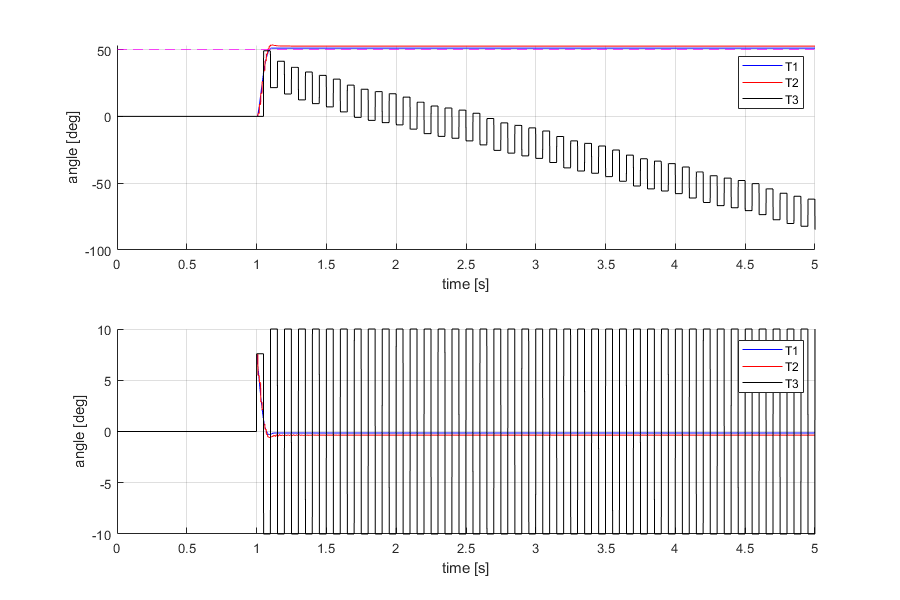

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1);
hold on;
plot(data2.nominal.forwe.samplingT1.t,data2.nominal.forwe.samplingT1.thl_meas,'b');
plot(data2.nominal.forwe.samplingT2.t,data2.nominal.forwe.samplingT2.thl_meas,'r');
plot(data2.nominal.forwe.samplingT3.t,data2.nominal.forwe.samplingT3.thl_meas,'k');
yline(50,'m--')
hold off;
legend('T1','T2','T3');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

subplot(2,1,2);
hold on;
plot(data2.nominal.forwe.samplingT1.t,squeeze(data2.nominal.forwe.samplingT1.u_control),'b');
plot(data2.nominal.forwe.samplingT2.t,squeeze(data2.nominal.forwe.samplingT2.u_control),'r');
plot(data2.nominal.forwe.samplingT3.t,data2.nominal.forwe.samplingT3.u_control,'k');

hold off;
legend('T1','T2','T3');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

stepinfo(data2.nominal.forwe.samplingT1.thl_meas,data2.nominal.forwe.samplingT1.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0601
    SettlingTime: 1.0840
     SettlingMin: 46.2305
     SettlingMax: 51.0645
       Overshoot: 0
      Undershoot: 0
            Peak: 51.0645
        PeakTime: 1.1070


stepinfo(data2.nominal.forwe.samplingT2.thl_meas,data2.nominal.forwe.samplingT2.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0597
    SettlingTime: 1.0799
     SettlingMin: 50.4492
     SettlingMax: 53.4375
       Overshoot: 1.6722
      Undershoot: 0
            Peak: 53.4375
        PeakTime: 1.1100


2) Robust tracking with Forward Euler

% open simulink model
open_system('REALTIME_PART2_robust.slx');

%poles
sigma=-spec.damp*spec.wn;
omega_d=spec.wn*sqrt(1-spec.damp^2);
p1 = [sigma+omega_d*j , sigma-omega_d*j , sigma ];
p2 = [sigma , sigma , sigma ];
p3 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 2*sigma ];
p4 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 3*sigma ];

%space model with augmented state
zer = zeros(2,1);
Ae=[0 C; zer A];
Be=[0; B];
Ce=[0 C];

Ke = acker(Ae,Be,p2);
K2 = [Ke(2) Ke(3)];
Ki = Ke(1);

step_size = 50;
ctrl.Kw = 0;

T = 0.001;
PHI = 1 + A0 * T;
GAMMA = B0 * T;
H0 = C0;
J0 = D0;
Ki = Ke(1);

%sim('REALTIME_PART2_robust');
data2.robust.forwe.samplingT1.t            = MotorData.time;
data2.robust.forwe.samplingT1.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.robust.forwe.samplingT1.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.robust.forwe.samplingT1.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.robust.forwe.samplingT1.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.01;
PHI = 1 + A0 * T;
GAMMA = B0 * T;
H0 = C0;
J0 = D0;
Ki = Ke(1);

%sim('REALTIME_PART2_robust');
data2.robust.forwe.samplingT2.t            = MotorData.time;
data2.robust.forwe.samplingT2.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.robust.forwe.samplingT2.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.robust.forwe.samplingT2.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.robust.forwe.samplingT2.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.05;
PHI = 1 + A0 * T;
GAMMA = B0 * T;
H0 = C0;
J0 = D0;
Ki = Ke(1);

%sim('REALTIME_PART2_robust');
data2.robust.forwe.samplingT3.t            = MotorData.time;
data2.robust.forwe.samplingT3.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.robust.forwe.samplingT3.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.robust.forwe.samplingT3.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.robust.forwe.samplingT3.u_control    = MotorData.signals(4).values;          % control input  [V]

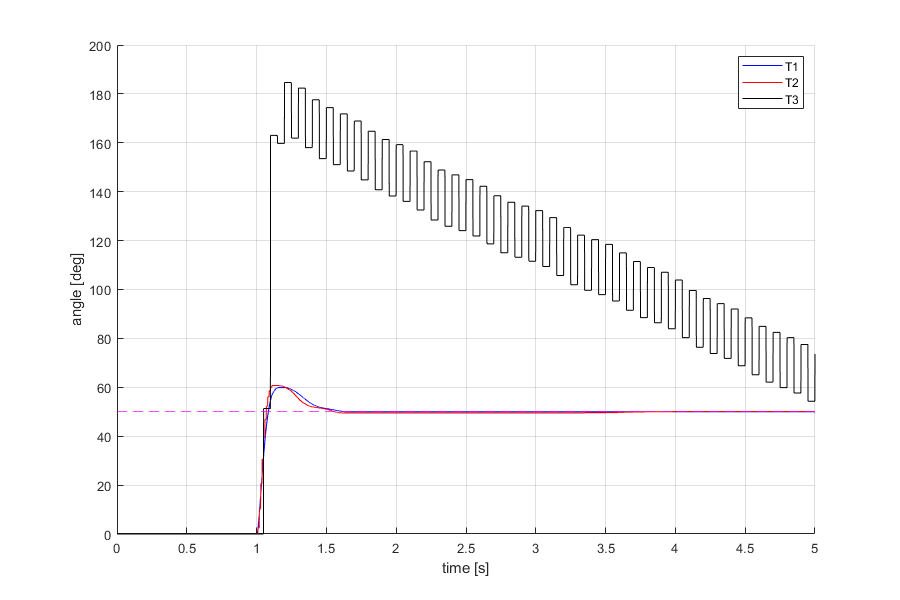

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data2.robust.forwe.samplingT1.t,data2.robust.forwe.samplingT1.thl_meas,'b');
plot(data2.robust.forwe.samplingT2.t,data2.robust.forwe.samplingT2.thl_meas,'r');
plot(data2.robust.forwe.samplingT3.t,data2.robust.forwe.samplingT3.thl_meas,'k');
yline(50,'m--')
hold off;
legend('T1','T2','T3');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

3) Nominal tracking with EXACT discretization 

% open simulink model
open_system('REALTIME_PART2_nominal.slx');

step_size = 50;
T = 0.001;
red_observer = ss(A0, B0, C0, D0);
sysCd = c2d(red_observer,T,'zoh');
[PHI,GAMMA,H0,J0] = ssdata(sysCd);

%sim('REALTIME_PART2_nominal.slx'); 
data2.nominal.exact.samplingT1.t            = MotorData.time;
data2.nominal.exact.samplingT1.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.nominal.exact.samplingT1.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.nominal.exact.samplingT1.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.nominal.exact.samplingT1.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.nominal.exact.samplingT1.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.01;
sysCd = c2d(red_observer,T,'zoh');
[PHI,GAMMA,H0,J0] = ssdata(sysCd);

%sim('REALTIME_PART2_nominal.slx'); 
data2.nominal.exact.samplingT2.t            = MotorData.time;
data2.nominal.exact.samplingT2.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.nominal.exact.samplingT2.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.nominal.exact.samplingT2.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.nominal.exact.samplingT2.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.nominal.exact.samplingT2.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.05;
sysCd = c2d(red_observer,T,'zoh');
[PHI,GAMMA,H0,J0] = ssdata(sysCd);

%sim('REALTIME_PART2_nominal.slx'); 
data2.nominal.exact.samplingT3.t            = MotorData.time;
data2.nominal.exact.samplingT3.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.nominal.exact.samplingT3.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.nominal.exact.samplingT3.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.nominal.exact.samplingT3.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.nominal.exact.samplingT3.u_control    = MotorData.signals(4).values;          % control input  [V]

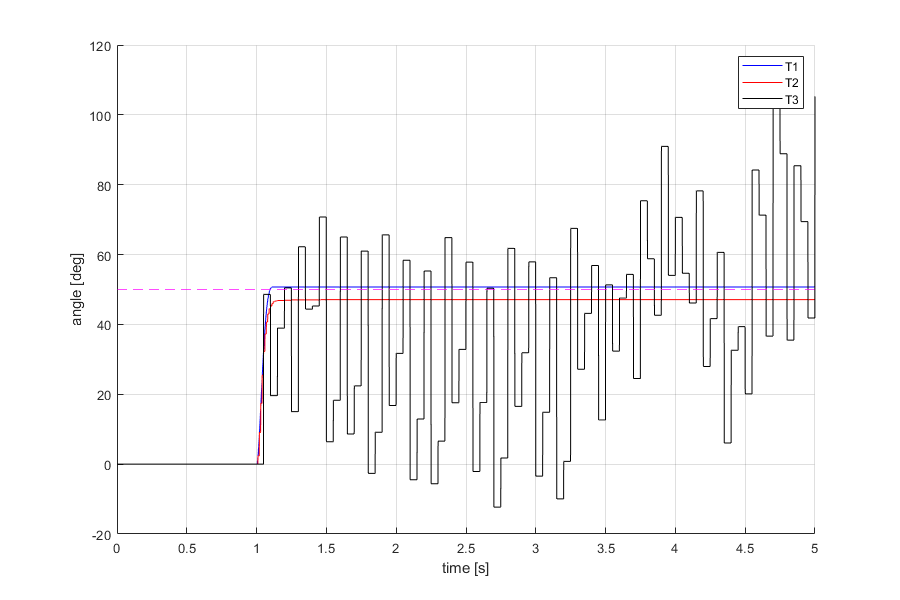

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data2.nominal.exact.samplingT1.t,data2.nominal.exact.samplingT1.thl_meas,'b');
plot(data2.nominal.exact.samplingT2.t,data2.nominal.exact.samplingT2.thl_meas,'r');
plot(data2.nominal.exact.samplingT3.t,data2.nominal.exact.samplingT3.thl_meas,'k');
yline(50,'m--')
hold off;
legend('T1','T2','T3');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

stepinfo(data2.nominal.exact.samplingT2.thl_meas,data2.nominal.exact.samplingT2.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0604
    SettlingTime: 1.0994
     SettlingMin: 42.9785
     SettlingMax: 47.1094
       Overshoot: 0
      Undershoot: 0
            Peak: 47.1094
        PeakTime: 1.4600


4) Robust tracking with EXACT discretization 

% open simulink model
open_system('REALTIME_PART2_robust_exact.slx');

step_size = 50;
T = 0.001;
sysCd = c2d(red_observer,T,'zoh');
[PHI,GAMMA,H0,J0] = ssdata(sysCd);
Ke = acker(Ae,Be,p2);
K2 = [Ke(2) Ke(3)];
Ki = Ke(1);
sysKe=tf(Ki,[1,0]);
sysKed = c2d(sysKe,T,'zoh');
[numKi,denKi]=tfdata(sysKed,'v');

%sim('REALTIME_PART2_robust_exact');
data2.robust.exact.samplingT1.t            = MotorData.time;
data2.robust.exact.samplingT1.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.robust.exact.samplingT1.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.robust.exact.samplingT1.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.robust.exact.samplingT1.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.01;
sysCd = c2d(red_observer,T,'zoh');
[PHI,GAMMA,H0,J0] = ssdata(sysCd);
sysKe=tf(Ki,[1,0]);
sysKed = c2d(sysKe,T,'zoh');
[numKi,denKi]=tfdata(sysKed,'v');

%sim('REALTIME_PART2_robust_exact');
data2.robust.exact.samplingT2.t            = MotorData.time;
data2.robust.exact.samplingT2.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.robust.exact.samplingT2.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.robust.exact.samplingT2.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.robust.exact.samplingT2.u_control    = MotorData.signals(4).values;          % control input  [V]

T = 0.05;
sysCd = c2d(red_observer,T,'zoh');
[PHI,GAMMA,H0,J0] = ssdata(sysCd);
sysKe=tf(Ki,[1,0]);
sysKed = c2d(sysKe,T,'zoh');
[numKi,denKi]=tfdata(sysKed,'v');

%sim('REALTIME_PART2_robust_exact');
data2.robust.exact.samplingT3.t            = MotorData.time;
data2.robust.exact.samplingT3.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.robust.exact.samplingT3.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.robust.exact.samplingT3.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.robust.exact.samplingT3.u_control    = MotorData.signals(4).values;          % control input  [V]

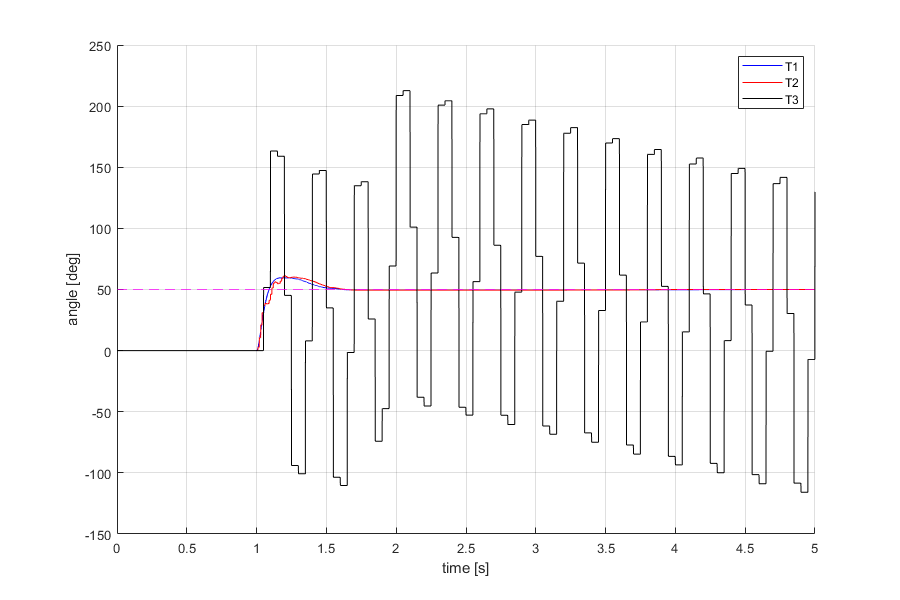

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data2.robust.exact.samplingT1.t,data2.robust.exact.samplingT1.thl_meas,'b');
plot(data2.robust.exact.samplingT2.t,data2.robust.exact.samplingT2.thl_meas,'r');
plot(data2.robust.exact.samplingT3.t,data2.robust.exact.samplingT3.thl_meas,'k');
yline(50,'m--')
hold off;
legend('T1','T2','T3');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

## **Part 3: Direct Digital Design**

1) Nominal tracking

% open simulink model
open_system('REALTIME_PART3_direct_digital_nominal.slx');

step_size = 50;

% First samplig-time
T = 0.001;

%discretize Plant
sysP = c2d(sys,T,'zoh');
[PHI,GAMMA,H,J] = ssdata(sysP);

lambda0 = -ctrl.w_gc*5;
lambda0 = exp(lambda0*T);

%Compute observer matrix
L= place(PHI(2,2).',PHI(1,2).',lambda0);
PHI0 = PHI(2,2) - L* PHI(1,2);
GAMMA0 =[ GAMMA(2) - L * GAMMA(1), (PHI(2,2) -L * PHI(1,2)) * L + PHI(2,1) - L * PHI(1,1)];
H0 = [0,1].';
J0 = [0,1 ; 0, L];

% feedforward gains
S = [PHI-eye(2),GAMMA;H,J];
b=[0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);

%poles to place
Ts = tf([spec.wn^2],[1, 2*spec.damp*spec.wn,spec.wn^2]);
p=pole(Ts);

%Compute feedback matrix
p = exp(p*T);
K=place(PHI,GAMMA,p);

%sim('REALTIME_PART3_direct_digital_nominal');
data2.directdig.nominal.samplingT1.t            = MotorData.time;
data2.directdig.nominal.samplingT1.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.directdig.nominal.samplingT1.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.directdig.nominal.samplingT1.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.directdig.nominal.samplingT1.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.directdig.nominal.samplingT1.u_control    = MotorData.signals(4).values;          % control input  [V]

% Second samplig-time
T = 0.01;
sysP = c2d(sys,T,'zoh');
[PHI,GAMMA,H,J] = ssdata(sysP);

lambda0 = -ctrl.w_gc*5;
lambda0 = exp(lambda0*T);

%Compute observer matrix
L= place(PHI(2,2).',PHI(1,2).',lambda0);
PHI0 = PHI(2,2) - L* PHI(1,2);
GAMMA0 =[ GAMMA(2) - L * GAMMA(1), (PHI(2,2) -L * PHI(1,2)) * L + PHI(2,1) - L * PHI(1,1)];
H0 = [0,1].';
J0 = [0,1 ; 0, L];

% feedforward gains
S = [PHI-eye(2),GAMMA;H,J];
b=[0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);
%poles to place
Ts = tf([spec.wn^2],[1, 2*spec.damp*spec.wn,spec.wn^2]);
p=pole(Ts);

%Compute feedback matrix
p = exp(p*T);
K=place(PHI,GAMMA,p);

%sim('REALTIME_PART3_direct_digital_nominal');
data2.directdig.nominal.samplingT2.t            = MotorData.time;
data2.directdig.nominal.samplingT2.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.directdig.nominal.samplingT2.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.directdig.nominal.samplingT2.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.directdig.nominal.samplingT2.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.directdig.nominal.samplingT2.u_control    = MotorData.signals(4).values;          % control input  [V]

% Third samplig-time
T = 0.05;

sysP = c2d(sys,T,'zoh');
[PHI,GAMMA,H,J] = ssdata(sysP);

lambda0 = -ctrl.w_gc*5;
lambda0 = exp(lambda0*T);
%Compute observer matrix
L= place(PHI(2,2).',PHI(1,2).',lambda0);
PHI0 = PHI(2,2) - L* PHI(1,2);
GAMMA0 =[ GAMMA(2) - L * GAMMA(1), (PHI(2,2) -L * PHI(1,2)) * L + PHI(2,1) - L * PHI(1,1)];
H0 = [0,1].';
J0 = [0,1 ; 0, L];

% feedforward gains
S = [PHI-eye(2),GAMMA;H,J];
b=[0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);
%poles to place
Ts = tf([spec.wn^2],[1, 2*spec.damp*spec.wn,spec.wn^2]);
p=pole(Ts);

%Compute feedback matrix
p = exp(p*T);
K=place(PHI,GAMMA,p);

%sim('REALTIME_PART3_direct_digital_nominal');
data2.directdig.nominal.samplingT3.t            = MotorData.time;
data2.directdig.nominal.samplingT3.thl_ref      = MotorData.signals(1).values(:,1);     % reference input [deg]
data2.directdig.nominal.samplingT3.thl_meas     = MotorData.signals(1).values(:,2);     % position measured [deg]
data2.directdig.nominal.samplingT3.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.directdig.nominal.samplingT3.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.directdig.nominal.samplingT3.u_control    = MotorData.signals(4).values;          % control input  [V]

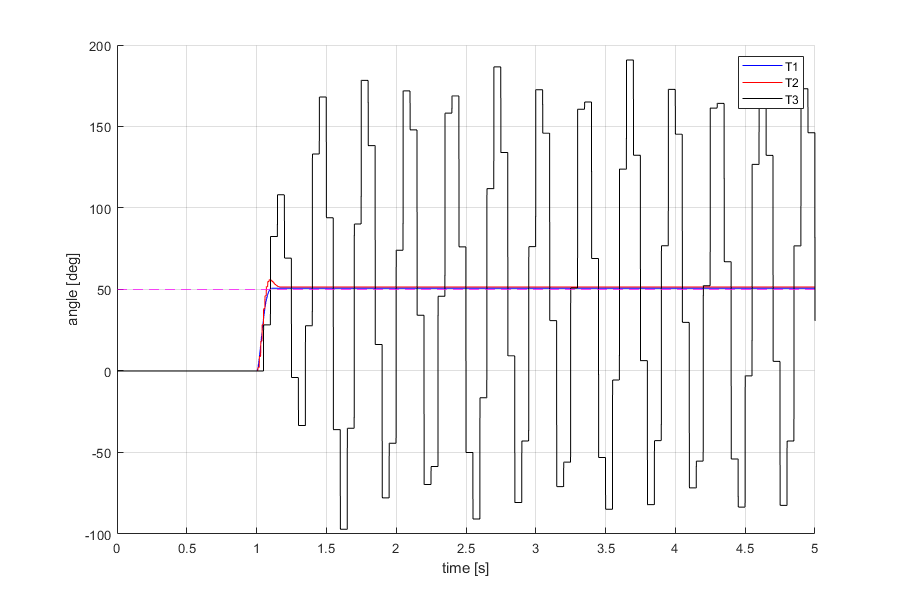

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data2.directdig.nominal.samplingT1.t,data2.directdig.nominal.samplingT1.thl_meas,'b');
plot(data2.directdig.nominal.samplingT2.t,data2.directdig.nominal.samplingT2.thl_meas,'r');
plot(data2.directdig.nominal.samplingT3.t,data2.directdig.nominal.samplingT3.thl_meas,'k');
yline(50,'m--')
hold off;
legend('T1','T2','T3');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

stepinfo(data2.directdig.nominal.samplingT1.thl_meas,data2.directdig.nominal.samplingT1.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0606
    SettlingTime: 1.0847
     SettlingMin: 45.8789
     SettlingMax: 50.8008
       Overshoot: 0
      Undershoot: 0
            Peak: 50.8008
        PeakTime: 1.1080


stepinfo(data2.directdig.nominal.samplingT2.thl_meas,data2.directdig.nominal.samplingT2.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0496
    SettlingTime: 1.1199
     SettlingMin: 51.5039
     SettlingMax: 55.9863
       Overshoot: 8.7031
      Undershoot: 0
            Peak: 55.9863
        PeakTime: 1.0900


2) Robust tracking

% open simulink model
open_system('REALTIME_PART2_robust.slx');

step_size = 50;
ctrl.Kw = 0;

% First samplig-time
T = 0.001;

sysP = c2d(sys,T,'zoh');
[Phi,Gamma,H,J] = ssdata(sysP);
lambda0 = -ctrl.w_gc*10;   %-ctrl.w_gc*5
lambda0 = exp(lambda0*T);

%Compute observer matrix
L= place(Phi(2,2).',Phi(1,2).',lambda0);
PHI = Phi(2,2) - L* Phi(1,2); %PHI0
GAMMA =[ Gamma(2) - L * Gamma(1), (Phi(2,2) -L * Phi(1,2)) * L + Phi(2,1) - L * Phi(1,1)]; %GAMMA0
H0 = [0,1].';
J0 = [0,1 ; 0, L];

% feedforward gains
S = [Phi-eye(2),Gamma;H,J];
b=[0 ,0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);

p1 = [sigma+omega_d*j , sigma-omega_d*j , sigma ];
p2 = [sigma , sigma , sigma ];
p3 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 2*sigma ];
p4 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 3*sigma ];

p = exp(p1*T);

zer = zeros(2,1);
PHIe = [1  , H;
        zer,Phi];
GAMMAe = [0;Gamma];
Ke = acker(PHIe,GAMMAe,p);
K2 = [Ke(2) Ke(3)];
Ki = Ke(1);

%sim('REALTIME_PART2_robust.slx');
data2.directdig.robust.samplingT1.t            = MotorData.time;
data2.directdig.robust.samplingT1.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.directdig.robust.samplingT1.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.directdig.robust.samplingT1.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.directdig.robust.samplingT1.u_control    = MotorData.signals(4).values;          % control input  [V]

% Second samplig-time
T = 0.01;

sysP = c2d(sys,T,'zoh');
[Phi,Gamma,H,J] = ssdata(sysP);
lambda0 = -ctrl.w_gc*5;
lambda0 = exp(lambda0*T);

%Compute observer matrix
L= place(Phi(2,2).',Phi(1,2).',lambda0);
PHI = Phi(2,2) - L* Phi(1,2); %PHI0
GAMMA =[ Gamma(2) - L * Gamma(1), (Phi(2,2) -L * Phi(1,2)) * L + Phi(2,1) - L * Phi(1,1)]; %GAMMA0
H0 = [0,1].';
J0 = [0,1 ; 0, L];

% feedforward gains
S = [Phi-eye(2),Gamma;H,J];
b=[0 ,0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);

p = exp(p1*T);
zer = zeros(2,1);
PHIe = [1  , H;
        zer,Phi];
GAMMAe = [0;Gamma];
Ke = acker(PHIe,GAMMAe,p);

K2 = [Ke(2) Ke(3)];
Ki = Ke(1);

%sim('REALTIME_PART2_robust.slx');
data2.directdig.robust.samplingT2.t            = MotorData.time;
data2.directdig.robust.samplingT2.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.directdig.robust.samplingT2.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.directdig.robust.samplingT2.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.directdig.robust.samplingT2.u_control    = MotorData.signals(4).values;          % control input  [V]

% Third samplig-time
T = 0.05;

sysP = c2d(sys,T,'zoh');
[Phi,Gamma,H,J] = ssdata(sysP);
lambda0 = -ctrl.w_gc*5;
lambda0 = exp(lambda0*T);

%Compute observer matrix
L= place(Phi(2,2).',Phi(1,2).',lambda0);
PHI = Phi(2,2) - L* Phi(1,2); %PHI0
GAMMA =[ Gamma(2) - L * Gamma(1), (Phi(2,2) -L * Phi(1,2)) * L + Phi(2,1) - L * Phi(1,1)]; %GAMMA0
H0 = [0,1].';
J0 = [0,1 ; 0, L];

% feedforward gains
S = [Phi-eye(2),Gamma;H,J];
b=[0 ,0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);

p = exp(p1*T);
zer = zeros(2,1);
PHIe = [1  , H;
        zer,Phi];
GAMMAe = [0;Gamma];
Ke = acker(PHIe,GAMMAe,p);
K2 = [Ke(2) Ke(3)];
Ki = Ke(1);

%sim('REALTIME_PART2_robust.slx');
data2.directdig.robust.samplingT3.t            = MotorData.time;
data2.directdig.robust.samplingT3.thl_meas     = MotorData.signals(1).values;          % position measured [deg]
data2.directdig.robust.samplingT3.wl_meas      = MotorData.signals(2).values;          % speed measured [rpm]
data2.directdig.robust.samplingT3.wl_est       = MotorData.signals(3).values;          % speed estimated [rpm]
data2.directdig.robust.samplingT3.u_control    = MotorData.signals(4).values;          % control input  [V]

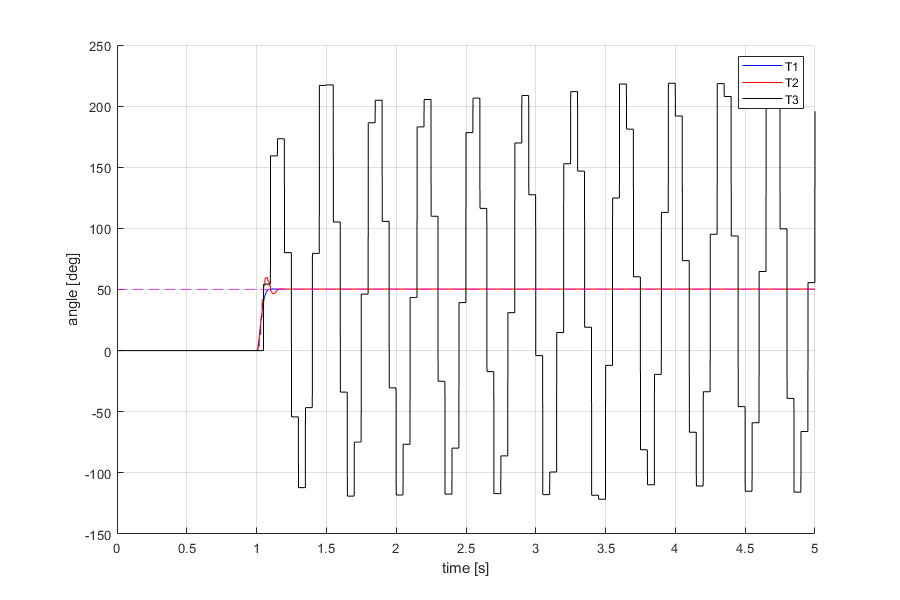

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data2.directdig.robust.samplingT1.t,data2.directdig.robust.samplingT1.thl_meas,'b');
plot(data2.directdig.robust.samplingT2.t,data2.directdig.robust.samplingT2.thl_meas,'r');
plot(data2.directdig.robust.samplingT3.t,data2.directdig.robust.samplingT3.thl_meas,'k');
yline(50,'m--')
hold off;
legend('T1','T2','T3');
xlabel('time [s]');
ylabel('angle [deg]');
grid on

stepinfo(data2.directdig.robust.samplingT1.thl_meas,data2.directdig.robust.samplingT1.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0483
    SettlingTime: 1.0688
     SettlingMin: 45.4395
     SettlingMax: 50.3613
       Overshoot: 0
      Undershoot: 0
            Peak: 50.3613
        PeakTime: 1.0930


stepinfo(data2.directdig.robust.samplingT2.thl_meas,data2.directdig.robust.samplingT2.t,"SettlingTimeThreshold",0.05)

ans = struct with fields:
        RiseTime: 0.0301
    SettlingTime: 1.1392
     SettlingMin: 46.6699
     SettlingMax: 59.9414
       Overshoot: 18.8153
      Undershoot: 0
            Peak: 59.9414
        PeakTime: 1.0700
